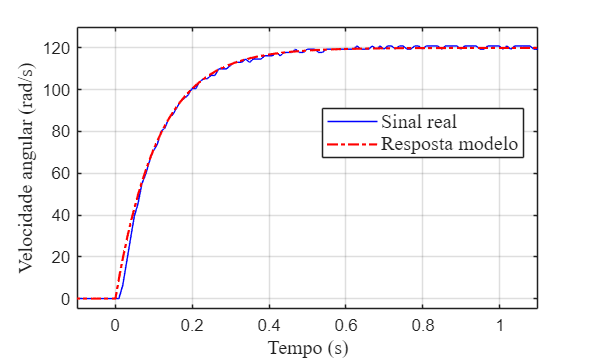

clc;
clearvars;
close all;

% Carregar dados do arquivo
data = load('motor.txt');

% Definir intervalo de tempo
inicio = 1;
final = 3000;

xInit = 0;
xFinal = 1.1;

tempo = data(inicio:final, 1)-41;
psi = data(inicio:final, 4)*57.296; % X
psi_dot = data(inicio:final, 5)*(2*pi/400)/(2*3.1415/3630); % X_dot
entrada = data(inicio:final, 7);

t = 0:0.01:29.99;
num = 24;
den = [0.11 1];
G = tf(num, den);
[simulado, ~, ~] = lsim(G, entrada, t);

figure;
plot(tempo, -psi_dot, 'b', 'LineWidth', 0.5);
hold on;
plot(t-1, simulado, '-.r', 'LineWidth', 1.3);
xlabel('Tempo (s)', 'FontSize', 12, 'FontName', 'Times New Roman')
ylabel('Velocidade angular (rad/s)', 'FontSize', 12, 'FontName', 'Times New Roman')
legend('Sinal real', 'Resposta modelo', 'Location', 'best', 'FontSize', 12, 'FontName', 'Times New Roman')
grid on;
xlim([xInit-0.1 xFinal]);
ylim([-5 130]);
hold off;